# Conversión entre modelos de imágenes RGB-HSV

Comenzamos con la generación de una imagen de color RGB de 2x2

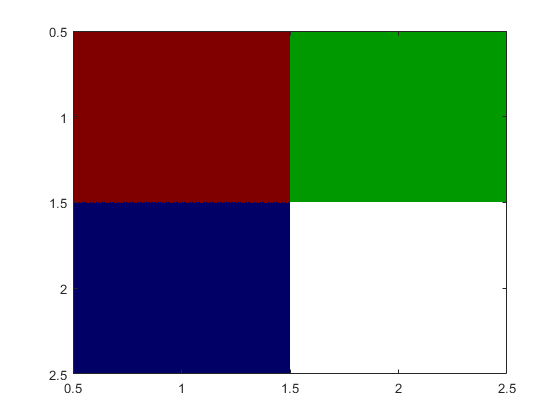

rgb(:,:,1) =    [0.5      0; 
                 0      1];
rgb(:,:,2) =    [0      0.6; 
                 0      1];
rgb(:,:,3) =    [0      0; 
                 0.4      1];
figure(1);
image(rgb);

El objetivo es generar un código basado en la transformación entre el modelo RGB y HSV

Para cada pixel

    Calcular cmax, cmin, diferencia

    cmax = max (r,g,b)

    cmin = min(r,g,b)

    Diferencia = cmax - cmin

        Cálculo de matiz (h):

            si cmax y cmin son iguales a 0, entonces h = 0

            si cmax es igual a r, entonces calcule h = (1/6 * ((g - b) / diff) + 1)% 1                // r = 0, 1

            si cmax es igual a g, entonces calcule h = (1/6 * ((b - r) / diff) + 1/3)% 1             // g = 1/3

            si cmax es igual a b, entonces calcule h = (1/6 * ((r - g) / diff) + 2/3)% 1             // b = 2/3

        Cálculo de saturación:

            si cmax = 0, entonces s = 0

            si cmax no es igual a 0, calcule s = (diff / cmax)

        Cálculo de valor:

            v = cmax

Es necesario conocer los indices donde se encuentra el valor máximo en cada matriz, recuerda que la imagen se guarda como un arreglo 3 dimensional, el tercer indice corresponde al color 

r=1, g = 2, b = 3;

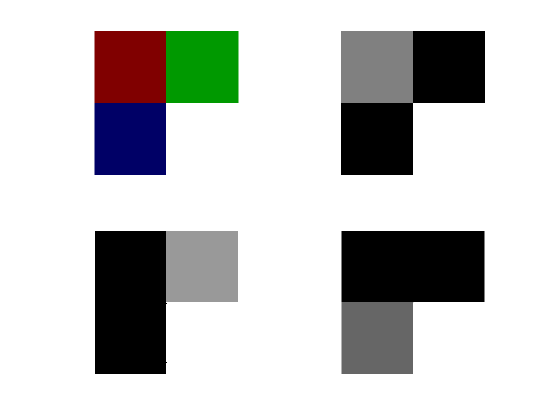

figure(2);
subplot(2,2,1);
imshow(rgb);
subplot(2,2,2);
imshow(rgb(:,:,1));
subplot(2,2,3);
imshow(rgb(:,:,2));
subplot(2,2,4);
imshow(rgb(:,:,3));

Puedes comparar el resultado de tu codigo con la función rgb2hsv()

hsv = hsv(:,:,1) =
     0.0000e+000   333.3333e-003
   666.6667e-003     0.0000e+000
hsv(:,:,2) =
     1.0000e+000     1.0000e+000
     1.0000e+000     0.0000e+000
hsv(:,:,3) =
   500.0000e-003   600.0000e-003
   400.0000e-003     1.0000e+000

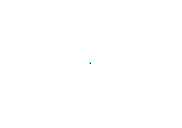

hsv = rgb2hsv(rgb)